Przykładowy sygnał xPi

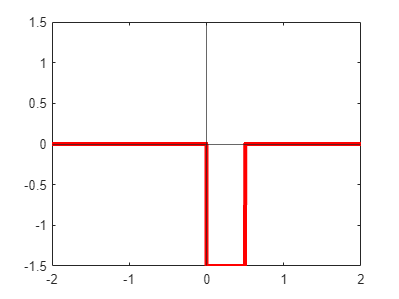

clc; clear; close all;
addpath("funkcje_pomocnicze");


okres_probkowania = 1/1000;
czas_poczatkowy = -2;
czas_koncowy = 2;
maskymalna_wartosc = 1.5;
minimalna_wartosc = -1.5;

amplituda = -1.5; % zmienna a w równaniu
opoznienie = 0.5; % zmienna c w równaniu
wydluzenie = 2; % zmienna b w równianiu

% poprawki żeby sygnał zachowywał się jak w równaniu przy podanych
% w przykładzie parametrach
opoznienie = opoznienie / 2;
wydluzenie = 1 / wydluzenie;


t = czas_poczatkowy : okres_probkowania : czas_koncowy;
wymiary_wykresu = [czas_poczatkowy, czas_koncowy, minimalna_wartosc, maskymalna_wartosc];
probki_sygnalu = xpi(t, amplituda, opoznienie, wydluzenie);

rysuj_wykres(wymiary_wykresu, t, probki_sygnalu, "r-", "LineWidth", 3);